# Relativ bevægelse

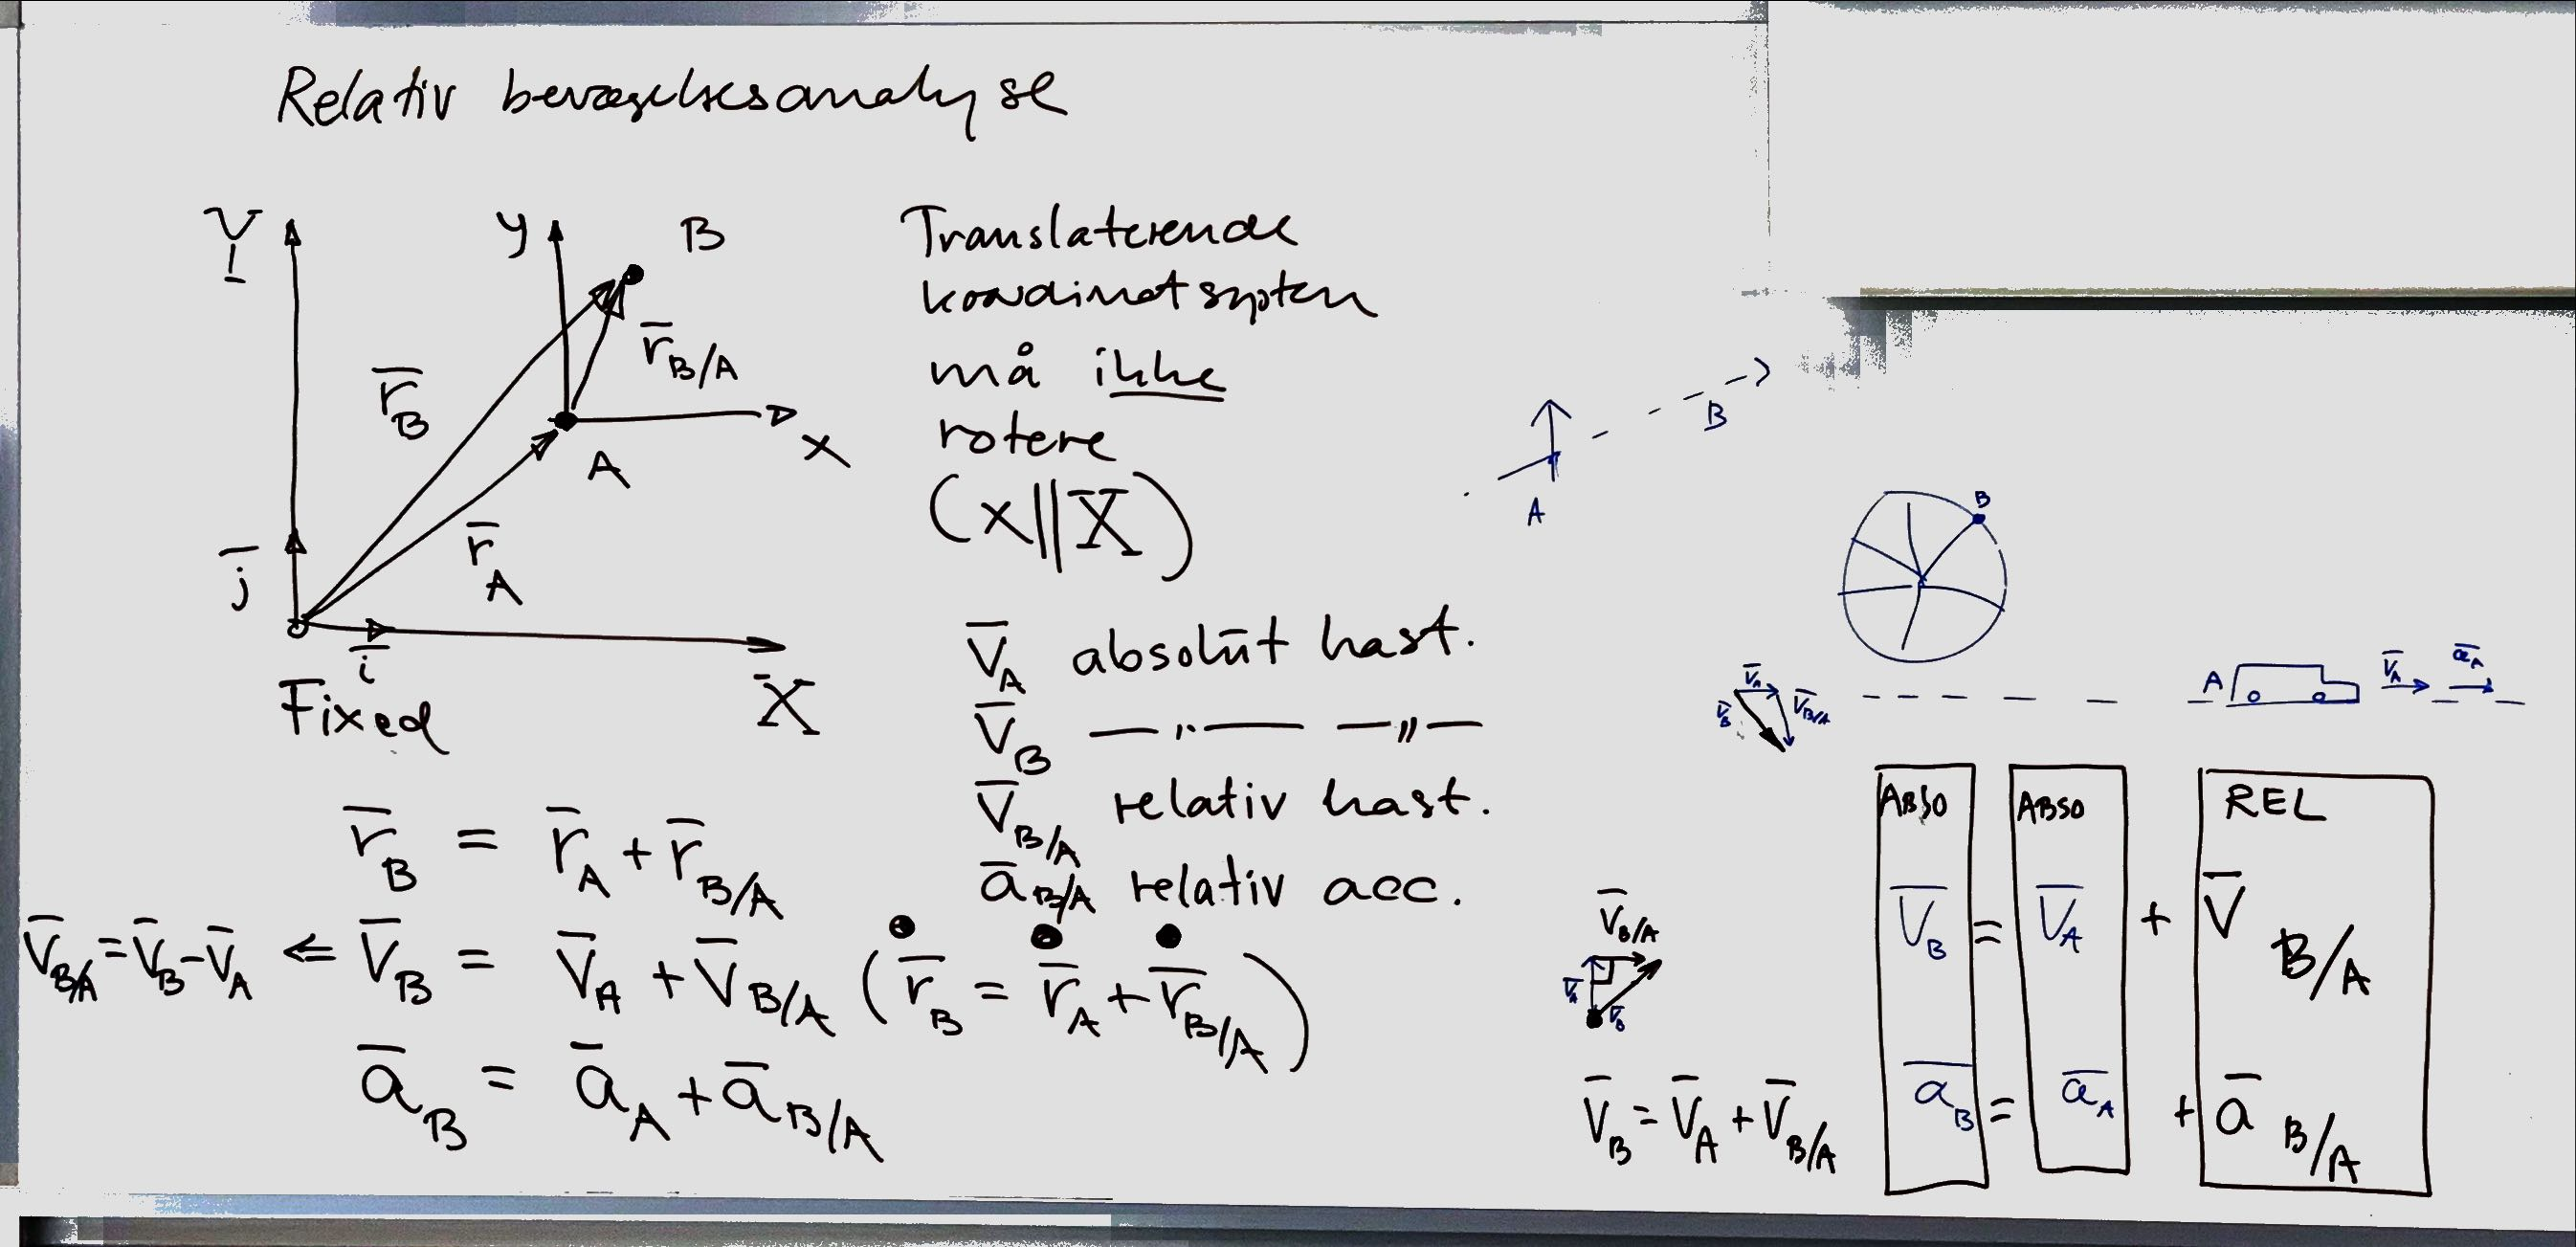

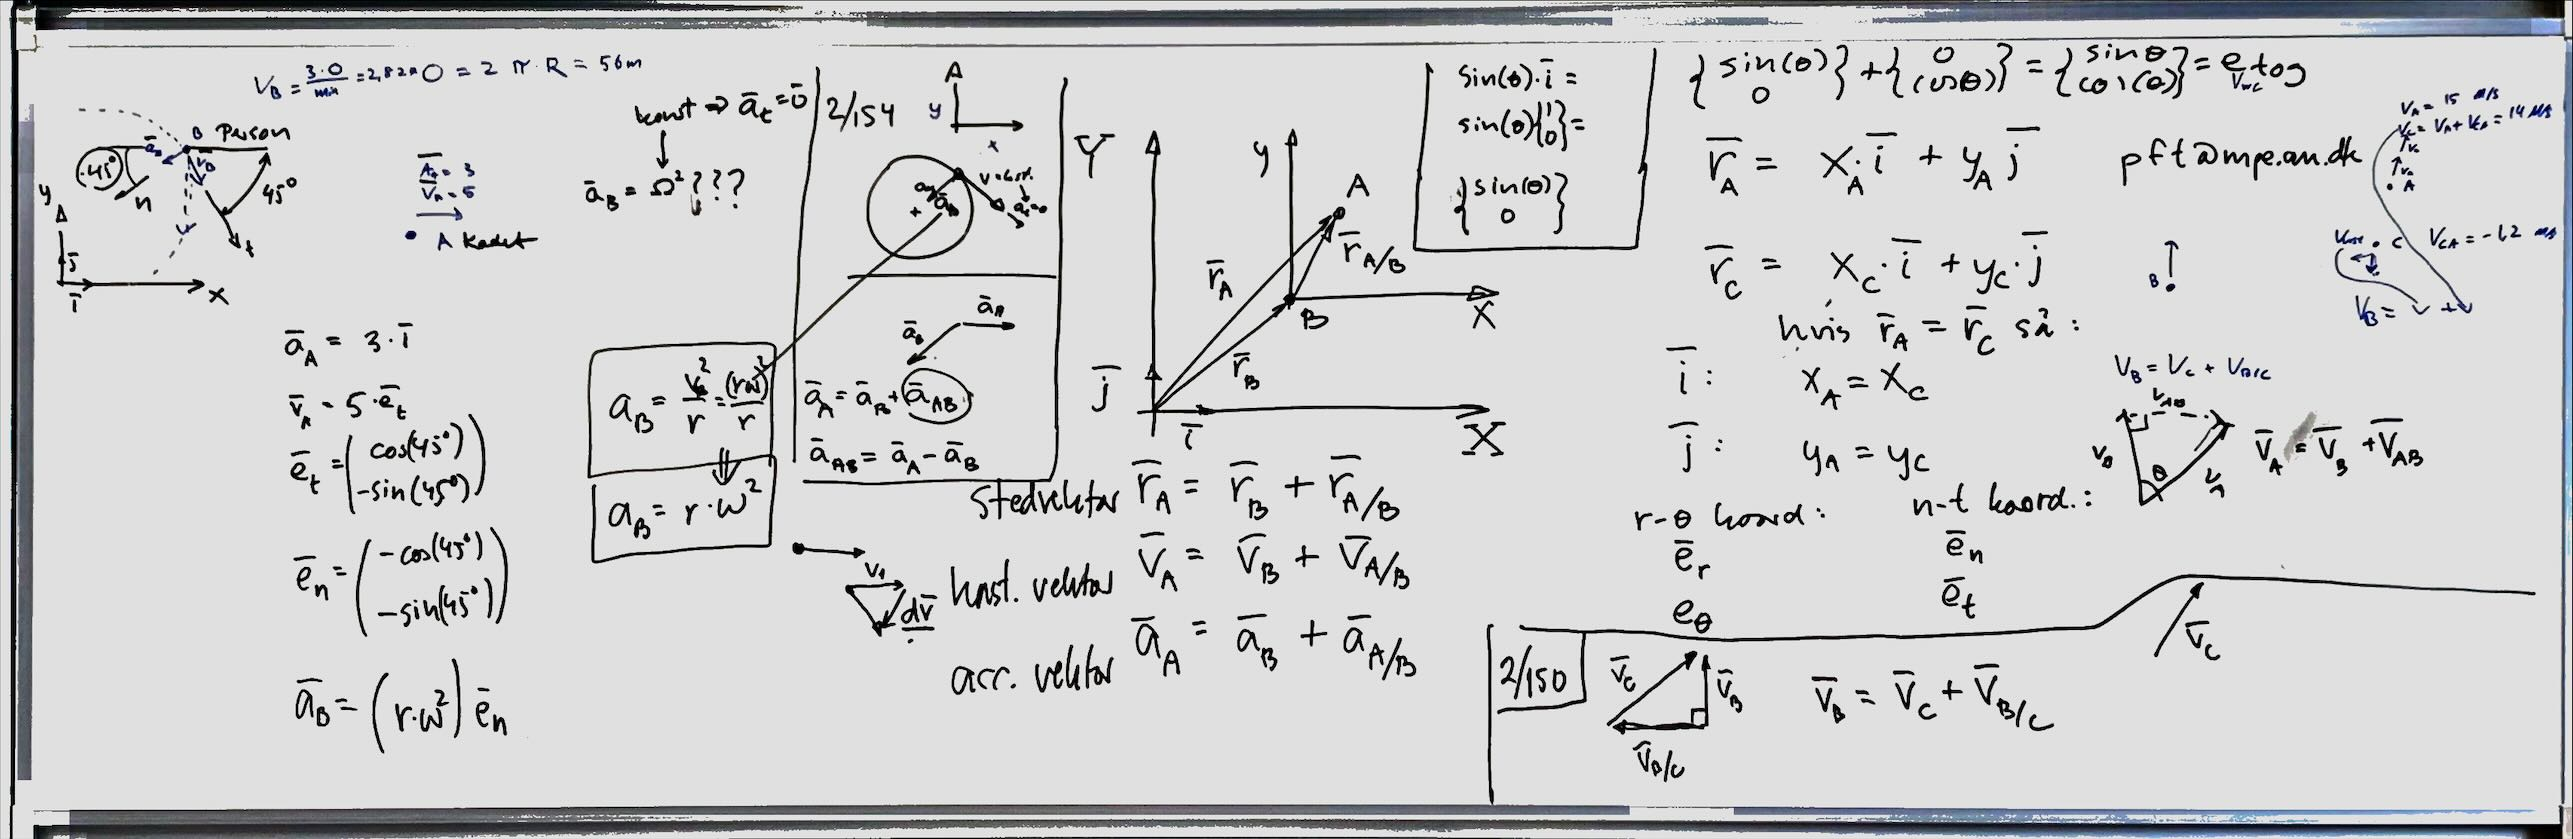

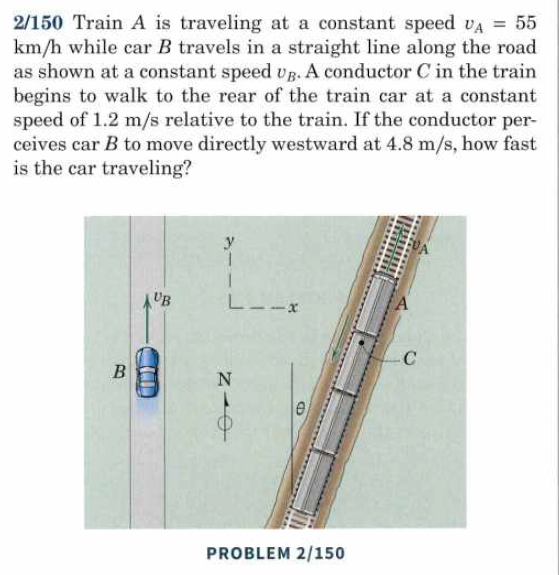

clear
va = 55/3.6;
v_obs = -1.2;

v_b_obs = 4.8;

v_c_tot = va + v_obs;

theta = asin(v_b_obs/v_c_tot);
rad2deg(theta)

ans = 19.9356


v_b = v_c_tot * cos(theta)

v_b = 13.2342

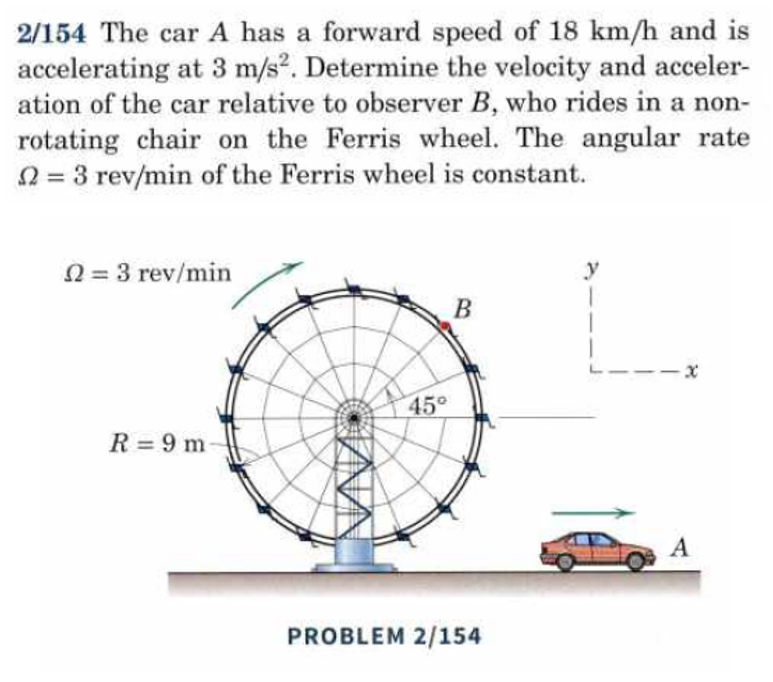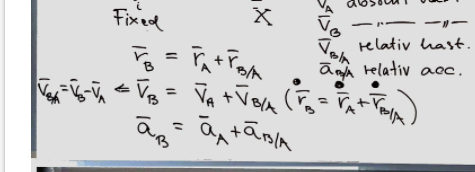


$$a_b = r\cdot \omega^2$$


clear

% Bil
v_A = [18/3.6; 0];
a_A = [3; 0];

% Hjul
omega = 3 * 2*pi/60;
R = 9;
theta = deg2rad(45);

v_b = R * omega; % Hjulets hastighed
a_B = R * omega^2;

angle_vec_hast = [cos(theta); -sin(theta)];

angle_vec_acc = [-cos(theta); -sin(theta)];

syms i j

vec = [i;j]

$$vec = \left(\begin{array}{c} i\\ j \end{array}\right)$$


v_ab = (v_A - v_b * (angle_vec_hast)).*vec;
vpa(v_ab, 3)

$$ans = \left(\begin{array}{c} 3.0\,i\\ 2.0\,j \end{array}\right)$$


a_ab = (a_A - a_B * (angle_vec_acc)).*vec;
vpa(a_ab, 3)

$$ans = \left(\begin{array}{c} 3.63\,i\\ 0.628\,j \end{array}\right)$$

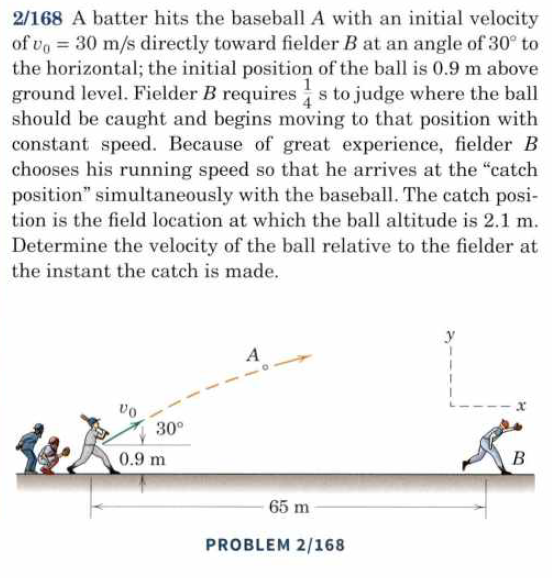

clear
g = -9.81;
v0 = 30;
theta = deg2rad(30);
y0 = 0.9;   ys = 2.1;
x0 = 0;

syms t
vy = sin(theta) * v0;
y = 1/2*g*t^2 + vy*t + y0 == ys;

t = max(solve(y, t));
t = vpa(t,3)

$$t = 2.98$$


vx = cos(theta) * v0;
R_bold = vx*t + x0;
R_bold = vpa(R_bold,3)

$$R\_bold = 77.3$$

R_mand = 65

R_mand = 65


R_d = R_bold - R_mand;
R_d = vpa(R_d, 3) % Så langt skal manden løbe for at nå bolden

$$R\_d = 12.3$$


ttid = 1/4;
v_mand = R_d/(t-ttid);
v_mand = vpa(v_mand, 3) % Så hurtigt skal manden løbe for at nå bolden

$$v\_mand = 4.52$$



% Boldens hastigheder når den gribes
syms i j
v_bold_x = vpa(vx*i, 3)

$$v\_bold\_x = 26.0\,i$$

v_bold_y = vpa((vy + g*t)*j,4)

$$v\_bold\_y = -14.19\,j$$



displayFormula("v_ab = v_a - v_b")

$$v_{\mathrm{ab}}=v_{a}-v_{b}$$

v_bold_set_fra_mand = vpa((v_bold_x + v_bold_y) - v_mand*i, 3)

$$v\_bold\_set\_fra\_mand = 21.5\,i-14.2\,j$$